# B

h=@height;
tau=@maxTime;
a=0.01; h0=0.30; theta=pi/4; g = 9.8;
tMax = tau(a,h0,theta, g)

tMax = 44.5384

heights = h(a,h0,theta, g, 0:tMax)

heights =     0.3000    0.2973    0.2945    0.2917    0.2889    0.2860    0.2831    0.2802    0.2772    0.2741    0.2710    0.2678    0.2646    0.2613    0.2580    0.2546    0.2511    0.2475    0.2439    0.2402    0.2364    0.2325    0.2285    0.2243    0.2201    0.2158    0.2113    0.2066    0.2018    0.1969    0.1917    0.1863    0.1807    0.1748    0.1686    0.1620    0.1549    0.1474    0.1393    0.1303    0.1203    0.1089    0.0954    0.0781    0.0513


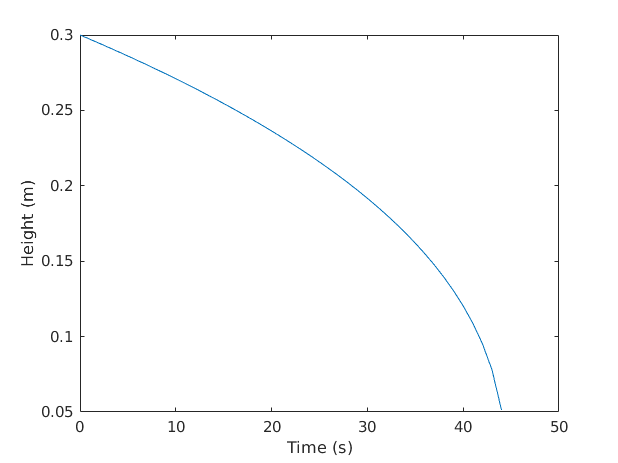

plot(0:tMax, heights);
xlabel('Time (s)'); ylabel('Height (m)');
print('eps/topic5_b.eps','-depsc')

# C

theta = linspace(pi/16, 7*pi/16,200);
h0=[0.30; 0.40];
tMax=tau(a,h0, theta, g)

tMax = 	1.0e+03 *

    1.1257    1.0590    0.9980    0.9420    0.8904    0.8429    0.7989    0.7582    0.7204    0.6852    0.6525    0.6220    0.5935    0.5668    0.5418    0.5183    0.4963    0.4755    0.4560    0.4376    0.4202    0.4037    0.3882    0.3735    0.3595    0.3463    0.3337    0.3217    0.3104    0.2995    0.2892    0.2794    0.2700    0.2610    0.2525    0.2443    0.2365    0.2290    0.2218    0.2149    0.2083    0.2019    0.1958    0.1900    0.1844    0.1790    0.1737    0.1687    0.1639    0.1593
    2.3108    2.1740    2.0487    1.9337    1.8279    1.7302    1.6399    1.5563    1.4788    1.4066    1.3395    1.2768    1.2183    1.1635    1.1121    1.0640    1.0187    0.9762    0.9361    0.8982    0.8625    0.8288    0.7969    0.7667    0.7380    0.7108    0.6850    0.6605    0.6371    0.6149    0.5937    0.5735    0.5543    0.5359    0.5183    0.5015    0.4854    0.4700    0.4552    0.4411    0.4275    0.4145    0.4020    0.3900    0.3785    0.3674    0.3567    0.3464

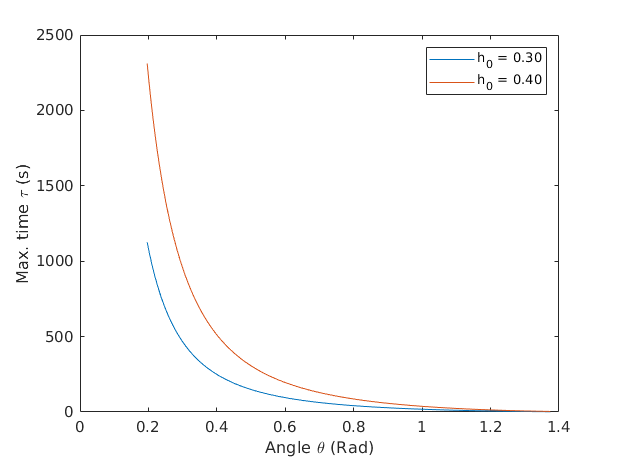

plot(theta, tMax(1,:)); hold on;
plot(theta, tMax(2,:));
xlabel('Angle \theta (Rad)'); ylabel('Max. time \tau (s)');
legend('h_0 = 0.30', 'h_0 = 0.40')
print('eps/topic5_c.eps','-depsc')

# F

t=[0:10:tMax/2 0:1:tMax/2 0:0.01:tMax/2];
vdot=@vdotf;
hdot=@hdotf;
a=0.01; h0=0.3; theta=pi/4; g=9.8;
tMax=tau(a,h0, theta, g)

tMax = 44.5384

V=integral(vdot(theta,t), 0,tMax/2)

Not enough input arguments.

Error in Untitled>hdotf (line 31)
    heightDerivative = 2/5*( h0.^(5/2)-t.*(h0^(5/2))./(tau) ).^(-3/5)*( (-h0.^(5/2))./(tau) );

Error in Untitled>vdotf (line 34)
    volumeDerivative = pi.*hdotf.*(h(t).*tan(pi/2-theta)).^2;

function tau = maxTime(a, h0, theta, g)
    tau = h0.^(5/2).*( 2.*tan(pi/2-theta).^2 )./( 5*a^2*sqrt(2*g) );
end
function h = height(a, h0, theta, g, t)
    h = ( h0.^(5/2) - t*( 5*a^2*sqrt(2*g) )./( 2.*tan(pi/2-theta).^2 ) ).^(2/5);
end

f

function dhdt = hdotf(h0,tau, t)
    dhdt = 2/5*( h0.^(5/2)-t.*(h0^(5/2))./(tau) ).^(-3/5)*( (-h0.^(5/2))./(tau) );
end
function dVdt = vdotf(h0,tau,theta,t)
    dVdt = pi.*hdotf(h0,tau,t).*(h(t).*tan(pi/2-theta)).^2;
end